VAV_st.name='VAV';
VAV_st.lat=56.02;
VAV_st.lon=13.15;
VAV_st.alt=172;


VAV_rd=read_betsy('vav_2008_2017',VAV_st.name);

datevec(VAV_rd.Time(1))

ans =         2008           1           2           0           0           0

datevec(VAV_rd.Time(end))

ans =         2018           1           1           0           0           0

prctile(VAV_rd.U_S11,[5 50 95])

ans =    12.3200   16.0000   28.7000

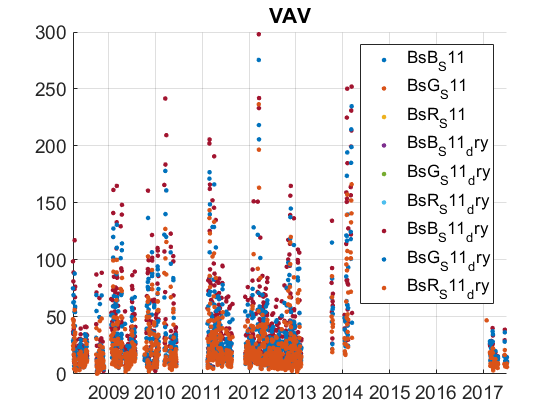

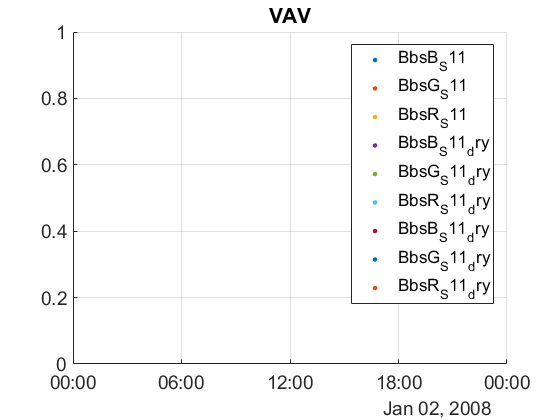

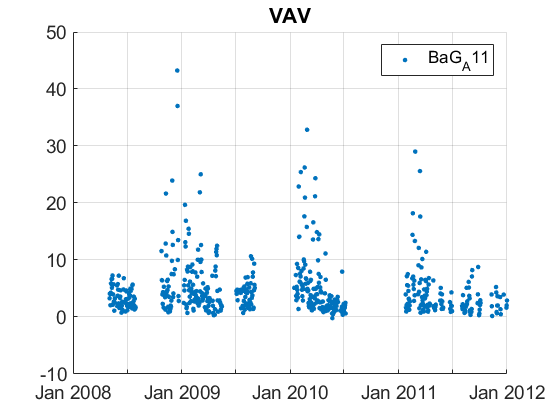

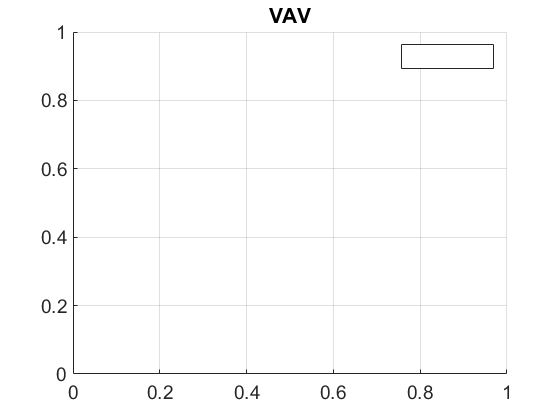

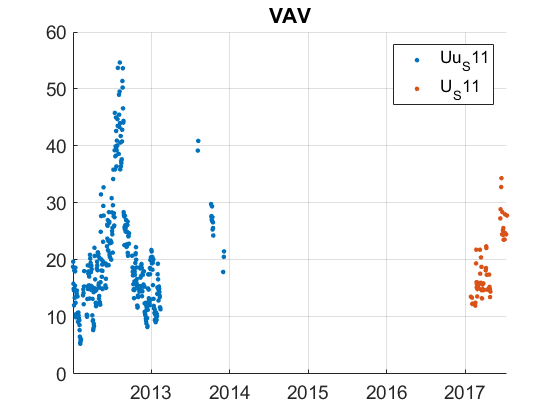

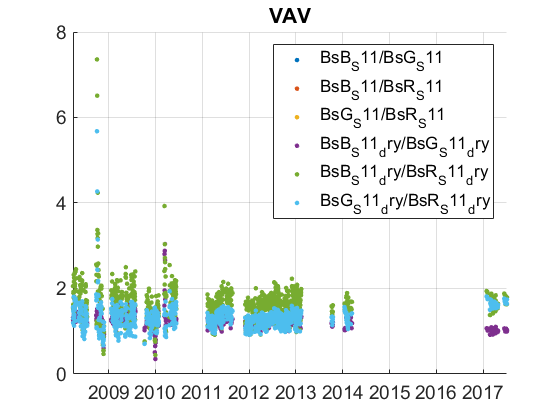

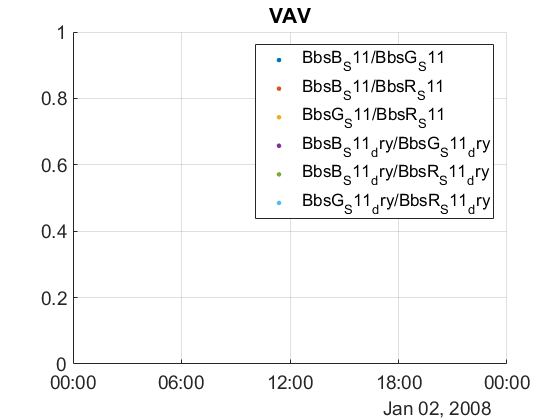

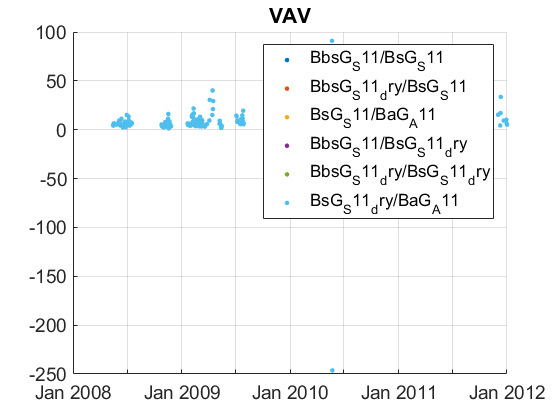

plotFigControl(VAV_rd,VAV_st.name);

% 1 size cut, 
% sc: ok, no clear seasonal cycle, few negatives
%with RH<50 almost no more data


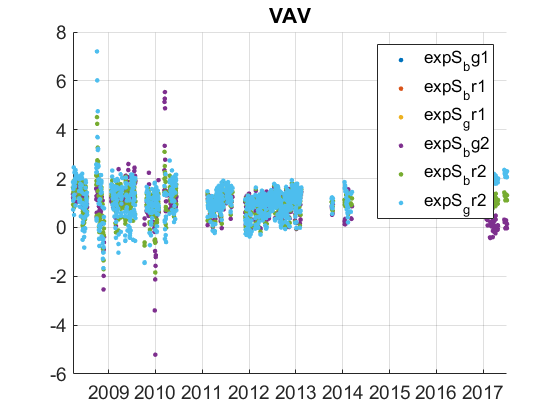

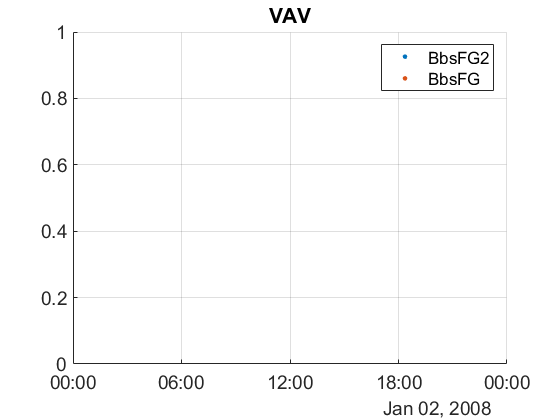

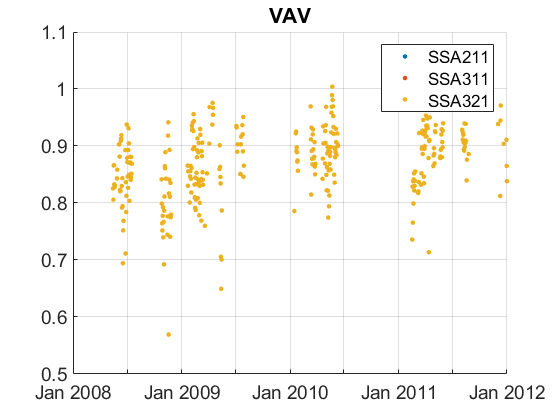

lambdaSC=[450;550;700]*ones(1,4);
lambdaAE=[467;529;653]*ones(1,4);
VAV_cal=compute_exp_SSA(VAV_rd,lambdaSC, lambdaAE);
plotFigControl_cal(VAV_cal,VAV_st.name);

%Questions:
%problems:
%



%scat  begin end March 2008, end July 2017, nothing from mid 2014 to 2017
%abs: begin may 2008, end 31 december 2011
% Rh only in 2013 and 2017
% --> not complete enough (and not long enough) to compute and 